clear all;
file = load('step1.mat');

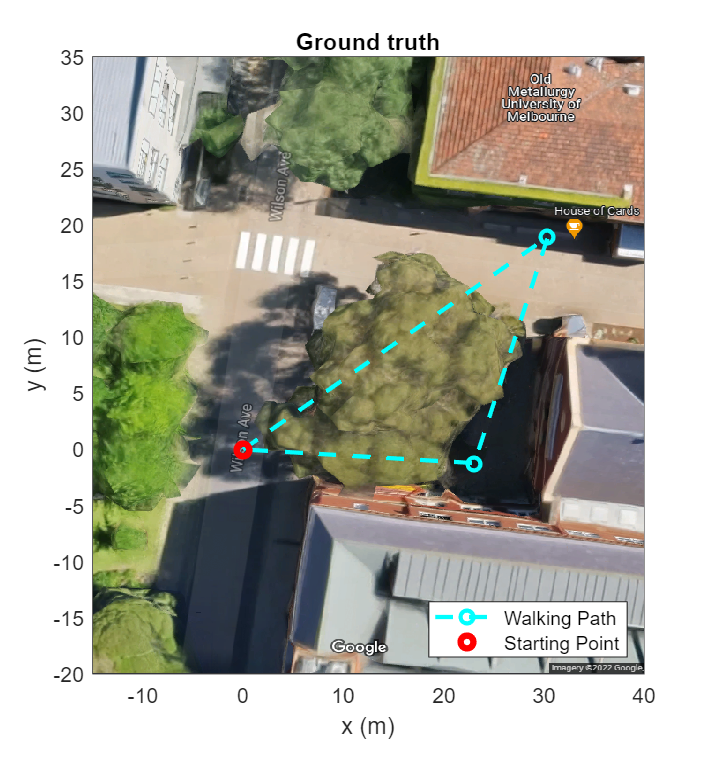

% Ground truth plotting
fig=gcf;
fig.Position(4)=595;


% 3 checkpoints
cp1 = [-37.799331, 144.961263, 0];
cp2 = [-37.79916028212808, 144.9616082566491, 0];
cp3 = [-37.799342, 144.961525, 0];
% or -37.799360, 144.961542

% Get movement vector between 3 checkpoints
r12 = lla2enu(cp2,cp1,'flat');
r23 = lla2enu(cp3,cp2,'flat');
r31 = lla2enu(cp1,cp3,'flat');

% Plotting
checkpoints_x = [0,r12(1),r12(1)+r23(1),0] ;
checkpoints_y = [0,r12(2),r12(2)+r23(2),0] ;
plot(checkpoints_x,checkpoints_y,'c--o',LineWidth=2)
title('Ground truth');
xlabel('x (m)');
ylabel('y (m)');

% Hard-define the plotting lim based on my Google Maps screenshot
xl = [-15,40];
yl = [35,-20];
% Add map for reference
hold on;
uistack(image(xl,yl,imread("map.png")),'bottom');
plot([0],[0],'ro',LineWidth=3);
legend('Walking Path','Starting Point',Location='southeast')
xlim(xl);
ylim([yl(2),yl(1)]);
hold off;

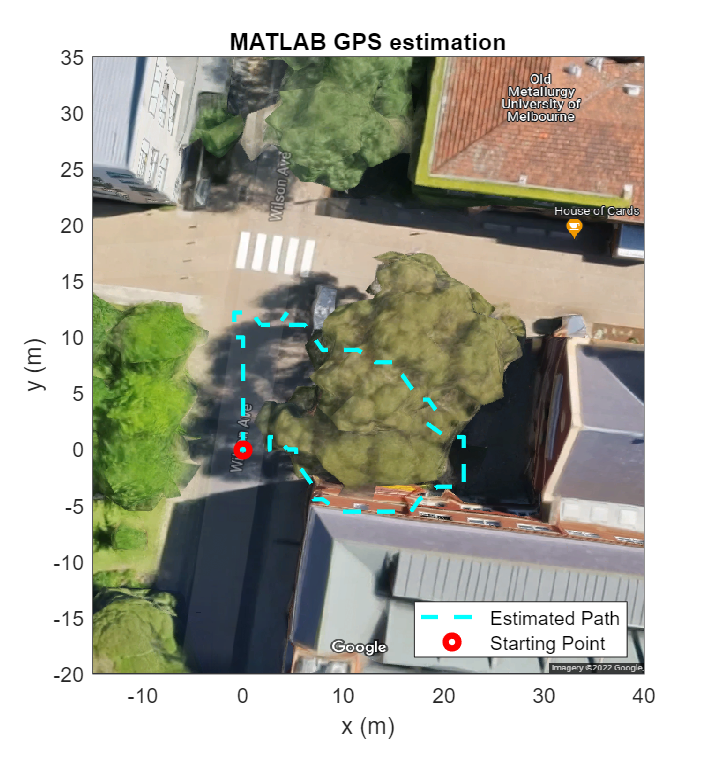

% GPS plotting
p = file.Position;
loc = [0,0,0];
cps = zeros(size(p,1),3);
for i=1:size(p,1)-1
    r = lla2enu([p.latitude(i+1),p.longitude(i+1),0], ...
        [p.latitude(i),p.longitude(i),0],'flat');
    loc = loc + r;
    cps(i+1,:) = loc;
end
plot(cps(:,1),cps(:,2),'c--',LineWidth=2)
title('MATLAB GPS estimation');
xlabel('x (m)');
ylabel('y (m)');

% Add map for reference
hold on;
uistack(image(xl,yl,imread("map.png")),'bottom');
plot([0],[0],'ro',LineWidth=3);
legend('Estimated Path','Starting Point',Location='southeast')
xlim(xl);
ylim([yl(2),yl(1)]);
hold off;